# STRESS CHECKING CALCULATOR

**Group 4 ASPR 2025**

## Setup and Data Preparation

clear; close all; clc;
% Read Excel moment data
momentFilename = 'MomentData.xlsx';
if ~isfile(momentFilename)
    error("MomentData.xlsx not found in current folder.");
end
load_data = readmatrix(momentFilename);

y_loc = load_data(2:end,1);
M_x_data = load_data(2:end,2);
V_z_data = load_data(2:end,3);
T_data   = load_data(2:end,4);
M_z = 0;

function arc = get_arc_map(x_arr, z_arr)
    dx = diff(x_arr);
    dz = diff(z_arr);
    arc = [0; cumsum(sqrt(dx.^2 + dz.^2))];
end

function s = get_dist_at_x(x_loc, x_up, arc_up, x_low, arc_low, surface)
    if strcmp(surface,'upper')
        s = interp1(x_up, arc_up, x_loc, 'linear', 'extrap');
    else
        s = interp1(x_low, arc_low, x_loc, 'linear', 'extrap');
    end
end

function [zu, zl] = get_z_at_x(x_loc, x_up, z_up, x_low, z_low)
    zu = interp1(x_up, z_up, x_loc, 'linear', 'extrap');
    zl = interp1(x_low, z_low, x_loc, 'linear', 'extrap');
end

function tightfig()
    try
        set(gcf,'renderer','painters'); drawnow;
    catch
    end
    outerpos = get(gcf,'OuterPosition');
    set(gcf,'Units','normalized','OuterPosition',outerpos);
end

### Geometry and Material Properties

A_sparcap = 0.0264;   % (m^2) 
A_stringer = 0.0118;  % (m^2)
t_skin = 0.00393;     % skin thickness (m)


% RIB / GEOMETRY INPUTS
y_ribs = [0, 3.2, 4.8, 6.18];   % spanwise stations to evaluate (m)
st_locations = [0.2786, 0.3572, 0.4358, 0.5144, 0.593, 0.6716]; % normalized chord
spar_x = [0.2, 0.75];  % normalized chord positions of front/rear spars

% MATERIAL PROPERTIES
E_7075 = 71.7e9;
E_2024  = 73.1e9;
nu_7075 = 0.03;
nu_2024  = 0.03;
sigma_yield_7075 = 503e6; % Pa
sigma_yield_2024  = 324e6; % Pa


% prepare storage
results = struct([]);
n_ribs = numel(y_ribs);

### Input Airfoil

% AIRFOIL FILE (normalized coords x,z)
airfoilFile = 'NACA 63-415.txt';
if ~isfile(airfoilFile)
    warning("Airfoil file '%s' not found. Aborting.", airfoilFile);
    return
end
af_data = load(airfoilFile);
x_norm = af_data(:,1);
z_norm = af_data(:,2);

% split upper/lower at leading edge (min x)
[~, le_idx] = min(x_norm);
x_up = flipud(x_norm(1:le_idx));
z_up = flipud(z_norm(1:le_idx));
x_low = x_norm(le_idx:end);
z_low = z_norm(le_idx:end);

% arc-length maps used by helper functions
arc_up = get_arc_map(x_up, z_up);
arc_low = get_arc_map(x_low, z_low);

## Each Section Analysis

for iR = 1:n_ribs
    y_pos = y_ribs(iR);
    % chord interpolation (same linear formula)
    c = 2.76 - 0.2639 * y_pos;
    Mx = interp1(y_loc, M_x_data, y_pos, 'linear','extrap');
    Vz = interp1(y_loc, V_z_data, y_pos, 'linear','extrap');
    Tt = interp1(y_loc, T_data, y_pos, 'linear','extrap');
    fprintf('Station y=%.3f m: Mx = %.6e\n', y_pos, Mx);

Station y=0.000 m: Mx = 3.168239e+05
Station y=3.200 m: Mx = 6.124838e+04
Station y=4.800 m: Mx = 1.235166e+04
Station y=6.180 m: Mx = 4.991348e+01


### Compute effective length b

    front_x = spar_x(1);
    rear_x  = spar_x(2);

    b1 = ( get_dist_at_x(front_x, x_up, arc_up, x_low, arc_low, 'lower') ...
         + get_dist_at_x(front_x, x_up, arc_up, x_low, arc_low, 'upper') ) * c;

    b2 = abs( get_dist_at_x(rear_x, x_up, arc_up, x_low, arc_low, 'upper') ...
            - get_dist_at_x(front_x, x_up, arc_up, x_low, arc_low, 'upper') ) * c;

    total_up = arc_up(end);
    total_low = arc_low(end);
    rem_up = total_up - get_dist_at_x(rear_x, x_up, arc_up, x_low, arc_low, 'upper');
    rem_low = total_low - get_dist_at_x(rear_x, x_up, arc_up, x_low, arc_low, 'lower');
    b3 = (rem_up + rem_low) * c;

    b4 = abs( get_dist_at_x(rear_x, x_up, arc_up, x_low, arc_low, 'lower') ...
            - get_dist_at_x(front_x, x_up, arc_up, x_low, arc_low, 'lower') ) * c;

    [zu_f, zl_f] = get_z_at_x(front_x, x_up, z_up, x_low, z_low);
    b5 = (zu_f - zl_f) * c;

    [zu_r, zl_r] = get_z_at_x(rear_x, x_up, z_up, x_low, z_low);
    b6 = (zu_r - zl_r) * c;

    b_array = [b1, b2, b3, b4, b5, b6];

### Compute area and centroid

    area_norm = trapz(x_up, z_up) - trapz(x_low, z_low);   % normalized
    planform_area = area_norm * c^2;

    mx_norm = trapz(x_up, x_up .* z_up) - trapz(x_low, x_low .* z_low);
    x_centroid = (mx_norm / area_norm) * c;

    mz_norm = 0.5 * ( trapz(x_up, z_up.^2) - trapz(x_low, z_low.^2) );
    z_centroid = (mz_norm / area_norm) * c;

### Define boom idealization

    nodes = [ front_x*c, zu_f*c;  rear_x*c, zu_r*c;  rear_x*c, zl_r*c;  front_x*c, zl_f*c ];
    x_star = nodes(:,1) - x_centroid;
    z_star = nodes(:,2) - z_centroid;
    A_boom = zeros(4,1);
    
    A_boom(1) = A_stringer * 3 + A_sparcap + t_skin * (b_array(1) + b_array(5))/6 * (2 + z_star(4)/z_star(1)) ...
                 + t_skin * b_array(2)/6 * (2 + z_star(2)/z_star(1));
    A_boom(2) = A_stringer * 3 + A_sparcap + t_skin * (b_array(3) + b_array(6))/6 * (2 + z_star(3)/z_star(2)) ...
                 + t_skin * b_array(2)/6 * (2 + z_star(1)/z_star(2));
    A_boom(3) = A_stringer * 3 + A_sparcap + t_skin * (b_array(3) + b_array(6))/6 * (2 + z_star(2)/z_star(3)) ...
                 + t_skin * b_array(4)/6 * (2 + z_star(4)/z_star(3));
    A_boom(4) = A_stringer * 3 + A_sparcap + t_skin * (b_array(1) + b_array(5))/6 * (2 + z_star(1)/z_star(4)) ...
                 + t_skin * b_array(4)/6 * (2 + z_star(3)/z_star(4));

### Inertia and Bending Stress Analysis

    I_xx = sum( A_boom .* (z_star.^2) );
    I_yy = sum( A_boom .* (x_star.^2) );
    I_xy = sum( A_boom .* (x_star .* z_star) );

    denom = (I_xx * I_yy - I_xy^2);
    k_xx = I_xx / denom;
    k_yy = I_yy / denom;
    k_xy = I_xy / denom;

    sigma_boom = zeros(4,1);
    for jj = 1:4
        s_val = -(k_xy * M_z + k_yy * Mx) * z_star(jj) + (k_xx * M_z + k_xy * Mx) * x_star(jj);
        sigma_boom(jj) = s_val;
    end

### Buckling Failure Analysis

    b_spar = (b_array(2) + b_array(4)) / 2;  % representative panel width (m)
    a_accum = 0;
    for xi = spar_x
        [zu_tmp, zl_tmp] = get_z_at_x(xi, x_up, z_up, x_low, z_low);
        a_accum = a_accum + abs(zu_tmp*c - zl_tmp*c);
    end
    h_spar = a_accum / numel(spar_x);
    m_mode = 1;
    k_buck = ( m_mode/(h_spar/b_spar) + (h_spar/b_spar)/m_mode )^2;
    sigma_buck = k_buck * pi^2 * E_7075 / (12 * (1 - nu_7075^2)) * (t_skin / b_spar)^2;

### Status Check

    status_each = repmat("OK",4,1);
    for jj = 1:4
        if jj <= 2
            allowable = sigma_buck / 2;
        else
            allowable = sigma_yield_2024 / 2;
        end
        if abs(sigma_boom(jj)) < allowable
            status_each(jj) = "Safe";
        else
            status_each(jj) = "Fail";
        end
    end
    if any(status_each == "Fail")
        overall_status = "Fail";
    else
        overall_status = "Safe";
    end

### Store Result

    res.id = iR;
    res.y = y_pos;
    res.chord = c;
    res.b_segments = round(b_array,4);
    res.planform_area = planform_area;
    res.centroid = [x_centroid, z_centroid];
    res.A_boom = round(A_boom,6);
    res.Inertia = [I_xx, I_yy, I_xy];
    res.k_vals = [k_xx, k_xy, k_yy];
    res.sigma_boom = round(sigma_boom,2);
    res.status_each = status_each;
    res.overall_status = overall_status;
    res.ideal_nodes = nodes;
    res.sigma_buck = sigma_buck;
    res.sigma_tension = sigma_yield_2024;

    results = [results; res];
end 

## Plotting

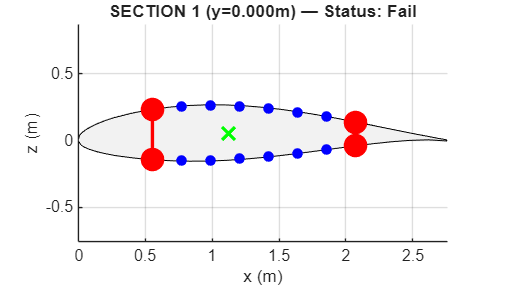

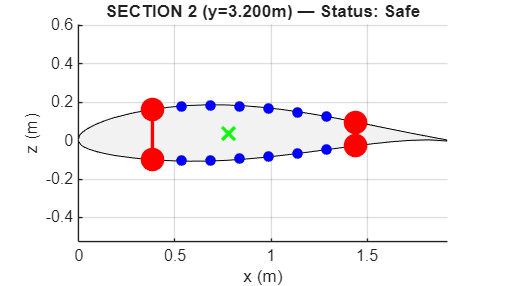

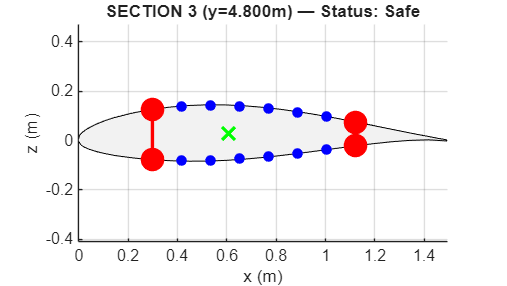

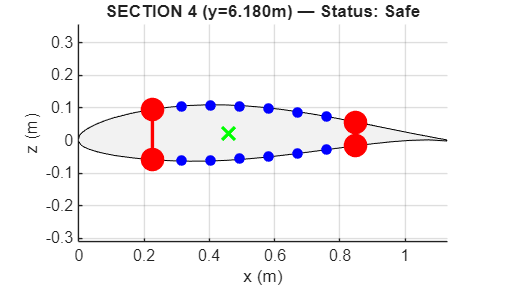

for i = 1:numel(results)
    R = results(i);
    c = R.chord;

    % create a new popup figure for this section
    fh = figure('Name', sprintf('SECTION %d - y=%.3fm', R.id, R.y), ...
                'NumberTitle','off', ...
                'Units','normalized', ...
                'OuterPosition',[0.15+0.1*(i-1), 0.15, 0.6, 0.6], ... % stagger windows a bit
                'WindowStyle','normal', ...
                'Color','w');

    hold on;

    % skin outline
    plot(x_norm * c, z_norm * c, 'k', 'LineWidth', 1.2);
    fill(x_norm * c, z_norm * c, [0.95 0.95 0.95], 'EdgeColor','none');

    % spars
    for xloc = spar_x
        [zu_tmp, zl_tmp] = get_z_at_x(xloc, x_up, z_up, x_low, z_low);
        plot([xloc*c, xloc*c], [zl_tmp*c, zu_tmp*c], 'r', 'LineWidth', 2);
    end

    % stringers
    for xs = st_locations
        [zu_s, zl_s] = get_z_at_x(xs, x_up, z_up, x_low, z_low);
        scatter(xs*c, zu_s*c, 40, 'b', 'filled');
        scatter(xs*c, zl_s*c, 40, 'b', 'filled');
    end

    % centroid
    scatter(R.centroid(1), R.centroid(2), 120, 'g', 'x', 'LineWidth', 2);

    % ideal nodes (red)
    scatter(R.ideal_nodes(:,1), R.ideal_nodes(:,2), 200, 'r', 'filled');

    title(sprintf('SECTION %d (y=%.3fm) — Status: %s', R.id, R.y, R.overall_status), 'Interpreter','none');
    axis equal; grid on;
    xlabel('x (m)'); ylabel('z (m)');
    hold off;

    pause(0.15);
end

## Reporting

n = numel(results);
if n == 0
    warning('No results to report.');
else
    fprintf('\n%s\n','==================== WING STRESS REPORT ====================');
    for i = 1:n
        R = results(i);
        fprintf('%s\n', repmat('-',1,60));
        fprintf('----- SECTION %d -----\n', R.id);
        fprintf('%s\n', repmat('-',1,60));
        fprintf('Chord = %.4f m   y = %.3f m   Status = %s\n', R.chord, R.y, R.overall_status);
        fprintf('Planform area = %.6e m^2   Centroid = (%.4f, %.4f) m\n', R.planform_area, R.centroid(1), R.centroid(2));
        fprintf('b_segments = [%s]\n', strjoin(string(R.b_segments), ', '));
        fprintf('A_boom (m^2) = [%s]\n', strjoin(string(R.A_boom), ', '));
        fprintf('Inertia (Ixx,Iyy,Ixy) = [%.6e, %.6e, %.6e]\n', R.Inertia(1), R.Inertia(2), R.Inertia(3));
        fprintf('k_vals (kxx,kxy,kyy) = [%.6e, %.6e, %.6e]\n', R.k_vals(1), R.k_vals(2), R.k_vals(3));
        fprintf('sigma_buck = %.3e Pa   sigma_tension (yield AL2024) = %.3e Pa\n', R.sigma_buck, R.sigma_tension);
        fprintf('%s\n',' +---------------- STRESSES PER BOOM ----------------+');
        for b = 1:4
            fprintf('  Boom %d : %8.3f MPa  (%.3e Pa)   | Status: %s\n', b, R.sigma_boom(b)/1e6, R.sigma_boom(b), R.status_each(b));
        end
        fprintf('%s\n', repmat('-',1,60));
    end
end


==================== WING STRESS REPORT ====================


------------------------------------------------------------


----- SECTION 1 -----


------------------------------------------------------------


Chord = 2.7600 m   y = 0.000 m   Status = Fail


Planform area = 7.136629e-01 m^2   Centroid = (1.1211, 0.0506) m


b_segments = [1.207, 1.5291, 1.3958, 1.5247, 0.3695, 0.1723]


A_boom (m^2) = [0.065247, 0.066911, 0.067032, 0.065348]


Inertia (Ixx,Iyy,Ixy) = [5.455392e-03, 1.629028e-01, 3.365461e-04]


k_vals (kxx,kxy,kyy) = [6.139414e+00, 3.787438e-01, 1.833282e+02]


sigma_buck = 1.322e+07 Pa   sigma_tension (yield AL2024) = 3.240e+08 Pa


 +---------------- STRESSES PER BOOM ----------------+


  Boom 1 :  -10.462 MPa  (-1.046e+07 Pa)   | Status: Fail
  Boom 2 :   -4.847 MPa  (-4.847e+06 Pa)   | Status: Safe
  Boom 3 :    5.160 MPa  (5.160e+06 Pa)   | Status: Safe
  Boom 4 :   10.997 MPa  (1.100e+07 Pa)   | Status: Safe


------------------------------------------------------------


------------------------------------------------------------


----- SECTION 2 -----


------------------------------------------------------------


Chord = 1.9155 m   y = 3.200 m   Status = Safe


Planform area = 3.437545e-01 m^2   Centroid = (0.7781, 0.0351) m


b_segments = [0.8377, 1.0613, 0.9687, 1.0582, 0.2564, 0.1196]


A_boom (m^2) = [0.064192, 0.065347, 0.065431, 0.064262]


Inertia (Ixx,Iyy,Ixy) = [2.581170e-03, 7.675990e-02, 1.596714e-04]


k_vals (kxx,kxy,kyy) = [1.302931e+01, 8.059943e-01, 3.874711e+02]


sigma_buck = 2.744e+07 Pa   sigma_tension (yield AL2024) = 3.240e+08 Pa


 +---------------- STRESSES PER BOOM ----------------+


  Boom 1 :   -2.967 MPa  (-2.967e+06 Pa)   | Status: Safe
  Boom 2 :   -1.374 MPa  (-1.374e+06 Pa)   | Status: Safe
  Boom 3 :    1.463 MPa  (1.463e+06 Pa)   | Status: Safe
  Boom 4 :    3.118 MPa  (3.118e+06 Pa)   | Status: Safe


------------------------------------------------------------


------------------------------------------------------------


----- SECTION 3 -----


------------------------------------------------------------


Chord = 1.4933 m   y = 4.800 m   Status = Safe


Planform area = 2.089092e-01 m^2   Centroid = (0.6066, 0.0274) m


b_segments = [0.653, 0.8273, 0.7552, 0.8249, 0.1999, 0.0932]


A_boom (m^2) = [0.063665, 0.064565, 0.064631, 0.06372]


Inertia (Ixx,Iyy,Ixy) = [1.554500e-03, 4.613058e-02, 9.629684e-05]


k_vals (kxx,kxy,kyy) = [2.168040e+01, 1.343039e+00, 6.433770e+02]


sigma_buck = 4.516e+07 Pa   sigma_tension (yield AL2024) = 3.240e+08 Pa


 +---------------- STRESSES PER BOOM ----------------+


  Boom 1 :   -0.775 MPa  (-7.745e+05 Pa)   | Status: Safe
  Boom 2 :   -0.359 MPa  (-3.587e+05 Pa)   | Status: Safe
  Boom 3 :    0.382 MPa  (3.821e+05 Pa)   | Status: Safe
  Boom 4 :    0.814 MPa  (8.140e+05 Pa)   | Status: Safe


------------------------------------------------------------


------------------------------------------------------------


----- SECTION 4 -----


------------------------------------------------------------


Chord = 1.1291 m   y = 6.180 m   Status = Safe


Planform area = 1.194368e-01 m^2   Centroid = (0.4586, 0.0207) m


b_segments = [0.4938, 0.6256, 0.571, 0.6238, 0.1511, 0.0705]


A_boom (m^2) = [0.06321, 0.063891, 0.06394, 0.063251]


Inertia (Ixx,Iyy,Ixy) = [8.817563e-04, 2.611792e-02, 5.468966e-05]


k_vals (kxx,kxy,kyy) = [3.829286e+01, 2.375059e+00, 1.134247e+03]


sigma_buck = 7.898e+07 Pa   sigma_tension (yield AL2024) = 3.240e+08 Pa


 +---------------- STRESSES PER BOOM ----------------+


  Boom 1 :   -0.004 MPa  (-4.172e+03 Pa)   | Status: Safe
  Boom 2 :   -0.002 MPa  (-1.932e+03 Pa)   | Status: Safe
  Boom 3 :    0.002 MPa  (2.058e+03 Pa)   | Status: Safe
  Boom 4 :    0.004 MPa  (4.385e+03 Pa)   | Status: Safe


------------------------------------------------------------
